% Declaring variables to derive the state space representation of system
% M is the Mass of cart
% m1 is the mass attached to pendulum 1
% m2 is the mass attached to pendulum 2
% l1 is the length of pendulum 1
% l2 is the length of pendulum 2
% g is the accleration due to gravity 
syms M m1 m2 l1 l2 g;

% Declaring the values of system variables
M_val = 1000;
m1_val = 100;
m2_val = 100;
l1_val = 20;
l2_val = 10;

A_val = [0 1 0 0 0 0;
         0 0 -(m1_val*9.81)/M_val 0 -(m2_val*9.81)/M_val 0;
         0 0 0 1 0 0;
         0 0 -((M_val+m1_val)*9.81/(M_val*l1_val)) 0 -(m2_val*9.81)/(M_val*l1_val) 0;
         0 0 0 0 0 1;
         0 0 -(m1_val*9.81)/(M_val*l2_val) 0 -((M_val+m2_val)*9.81/(M_val*l2_val)) 0];

% Declaring the B matrix of the system
B_val = [0; 1/M_val; 0; 1/(M_val*l1_val); 0; 1/(M_val*l2_val)];

% Defining the Q and R matrices for LQR controller
Q = [10  0  0  0  0  0;
     0  10  0  0  0  0;
     0   0 100 0  0  0;
     0   0  0  1  0  0;
     0   0  0  0 100 0;
     0   0  0  0  0  1];

R = 0.001;

% Finding the optimal closed-loop feedback gain using LQR
[K, R_soln, poles] = lqr(A_val,B_val,Q,R)

K =   100.0000  501.2631   23.4087 -331.8456   38.6244 -155.4583


R_soln = 1.0e+04 *

    0.0050    0.0121   -0.0033   -0.0205   -0.0016   -0.0104
    0.0121    0.0610    0.0038   -0.1094    0.0026   -0.0537
   -0.0033    0.0038    0.6780    0.0055    0.0026   -0.0177
   -0.0205   -0.1094    0.0055    1.4502    0.0229    0.0371
   -0.0016    0.0026    0.0026    0.0229    0.3401    0.0012
   -0.0104   -0.0537   -0.0177    0.0371    0.0012    0.3628


poles =   -0.0102 + 0.7277i
  -0.0102 - 0.7277i
  -0.0178 + 1.0423i
  -0.0178 - 1.0423i
  -0.2066 + 0.2023i
  -0.2066 - 0.2023i



C1 = [1 0 0 0 0 0];

D = 0;

% Defining the process and measurement noise
Vd = 0.2*eye(6);
Vn = 1;

% Finding the optimal observer gains for each observer
L1 = lqr(A_val', C1', Vd, Vn)

L1 =     2.1429    2.1960   -0.2843    0.5589   -0.3758    0.3826


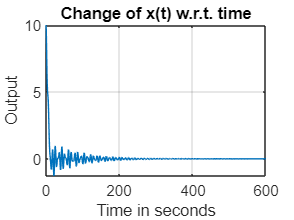



A_c1 = [(A_val - B_val*K) B_val*K; zeros(size(A_val)) (A_val - L1'*C1)];
B_c1 = [B_val; B_val];
C_c1 = [C1 zeros(size(C1))];

x0_lqg = [10;0;0.5;0;0.6;0];

% Plotting x(t) for non-linear system
t_span = 0:0.01:600;
[ts,x_dots] = ode45(@(t,x)non_lin_sys(t,x,-K*x,L1,C1),t_span,x0_lqg);
plot(ts,x_dots(:,1))
grid
xlabel('Time in seconds')
ylabel('Output')
title('Change of x(t) w.r.t. time')

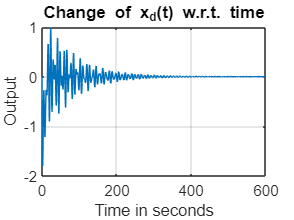


% Plotting x_d(t) for non-linear system
plot(ts,x_dots(:,2))
grid
xlabel('Time in seconds')
ylabel('Output')
title('Change of x_d(t) w.r.t. time')

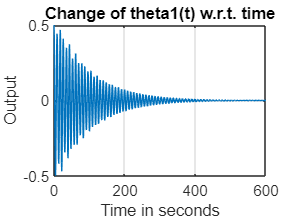


% Plotting theta1(t) for non-linear system
plot(ts,x_dots(:,3))
grid
xlabel('Time in seconds')
ylabel('Output')
title('Change of theta1(t) w.r.t. time')

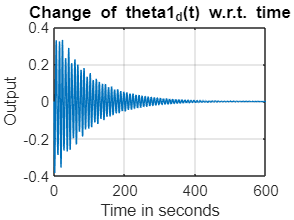


% Plotting theta1_dot(t) for non-linear system
plot(ts,x_dots(:,4))
grid
xlabel('Time in seconds')
ylabel('Output')
title('Change of theta1_d(t) w.r.t. time')

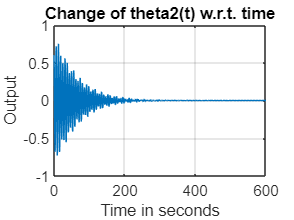


% Plotting theta2(t) for non-linear system
plot(ts,x_dots(:,5))
grid
xlabel('Time in seconds')
ylabel('Output')
title('Change of theta2(t) w.r.t. time')

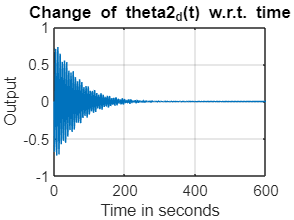


% Plotting theta2_dot(t) for non-linear system
plot(ts,x_dots(:,6))
grid
xlabel('Time in seconds')
ylabel('Output')
title('Change of theta2_d(t) w.r.t. time')

function x_dot = non_lin_sys(t,X,F,L,C)
x_dot = zeros(6,1);
% Declaring the values of system variables
M_val = 1000;
m1_val = 100;
m2_val = 100;
l1_val = 20;
l2_val = 10;
g_val = 9.81;
x = X(1);
x_d = X(2);
theta1 = X(3);
theta1_d = X(4);
theta2 = X(5);
theta2_d = X(6);
obs = L*(x-C*X);
x_dot(1) = x_d + obs(1);
x_dot(2) = (F-((m1_val*sin(theta1)*cos(theta1))+(m2_val*sin(theta2)*cos(theta2)))*g_val - (l1_val*m1_val*(x_dot(3)^2)*sin(theta1)) - (l2_val*m2_val*(x_dot(5)^2)*sin(theta2)))/(m1_val+m2_val+M_val-(m1_val*(cos(theta1)^2))-(m2_val*(cos(theta2)^2)))+obs(2);
x_dot(3) = theta1_d+obs(3);
x_dot(4) = ((cos(theta1)*x_dot(2)-g_val*sin(theta1))/l1_val) + obs(4);
x_dot(5) = theta2_d + obs(5);
x_dot(6) = (cos(theta2)*x_dot(2)-g_val*sin(theta2))/l2_val + obs(6);
end

